clear; clc; close all;

addpath('../scripts')

% Read the test data.
testDataFolderName = '20241016';
lenSeries = 1000; % Sequence length.
simulationTime = 10; % The time that this sequence corresponds to.
dataLoader = DataLoader(lenSeries, simulationTime);

% Instantiate a RobotSimulator class.
dt = .1;
steps = 10;
robotSimulator = RobotSimulator(steps, dt);
robotSimulator.simulinkMdl = 'main4_armpi_fpv.slx'; % Use the new version of the simulation model that considers the motor dynamics.

dataLoader.pathLoggedTestData = ['../dataset/testDatasets/' testDataFolderName '/real_testing_dataset.mat'];
dataLoader.pathTestDataset = ['../dataset/testDatasets/' testDataFolderName '/'];
dataLoader.pathOriginalTestData = ['../dataset/testDatasetsOriginal/' testDataFolderName '/'];
dataLoader.nTrajPerLabelTestDataset = 10;
dataLoader.labelList = {'Healthy', ...
    'Motor_1_Stuck', 'Motor_2_Stuck', 'Motor_3_Stuck', 'Motor_4_Stuck', ...
    'Motor_1_Steady_state_error', 'Motor_2_Steady_state_error', 'Motor_3_Steady_state_error', 'Motor_4_Steady_state_error'};
    
[X_test, y_test] = dataLoader.loadTestingData();

Loaded data from ../dataset/testDatasets/20241016/real_testing_dataset.mat


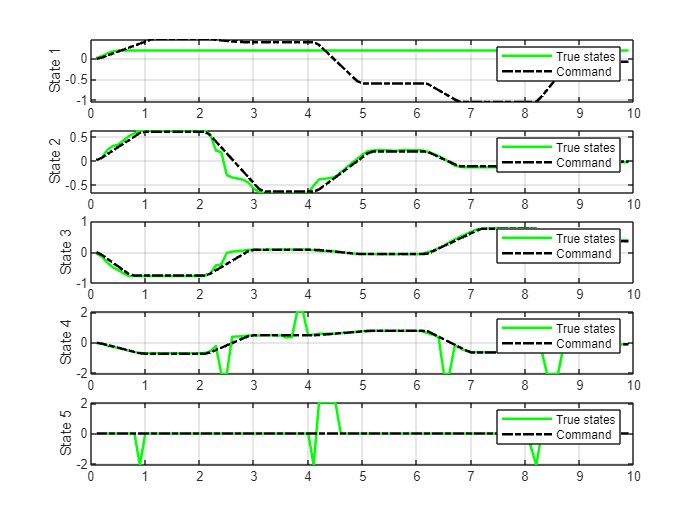

% Get one test data.
idx = 21;
dataset = X_test{idx};

% Extract the variables.
U = dataset{1:steps:end-steps, 2:6}; % Inputs
U(:, 5) = 0; % Fix the gripper position.
Z = dataset{steps+1:steps:end, 10:12}; % Observations
time = dataset{1:steps:end-steps, 1}; % Times

% Prepare the observer.
N = numel(time); % Number of steps.
state_dim = size(U, 2); % Number of states
obs_dim = size(Z, 2); % Number of observations

% Get the true response.
matfile_path = dataset.matFilePath{1};
matfile_path = strrep(matfile_path, 'dataset_', 'hidden_dataset_');
hidden_data_set = load(matfile_path);

x_true = zeros(state_dim, N);
for i = 1:state_dim
    x_true(i, :) = hidden_data_set.motorRespsRadius{i}.Data(steps+1:steps:end);
end

% Plot results
t = (1:N) * dt;
figure;
for i = 1:state_dim
    subplot(state_dim, 1, i);
    plot(t, x_true(i, :), 'g-', 'LineWidth', 1.5); hold on;
    plot(t, U(:, i), 'k-.', 'LineWidth', 1.5); hold on;
    ylabel(['State ', num2str(i)]);
    legend('True states', 'Command');
    grid on;
end

% State variables initialization
% x_true = zeros(state_dim, 1); % True initial state
x_est = zeros(state_dim, 1); % Estimated initial state
P = eye(state_dim); % Initial state covariance

% Input and noise parameters
Q = 0.001 * eye(state_dim); % Process noise covariance
R = 0.0001 * eye(obs_dim); % Measurement noise covariance
delta = 1e-5; % Perturbation size for numerical Jacobian

% Define simulation model placeholders
f_sim = @(x, u) simulation_state_transition(x, u, robotSimulator, steps); % Placeholder for simulation state transition
h_sim = @(x) simulation_observation(x, robotSimulator); % Placeholder for simulation observation

% Numerical Jacobian approximation
numerical_jacobian = @(f, x, u, delta) compute_jacobian(f, x, u, delta);

% Simulation and estimation
% x_history = zeros(state_dim, N);
z_est_history = zeros(obs_dim, N);
x_est_history = zeros(state_dim, N);

for k = 1:N
    fprintf('%d / %d th iteration:\n', k, N);

    % Get the observed value at the current step.
    z = transpose(Z(k, :));
    u = transpose(U(k, :));
    
    % Prediction step
    x_pred = f_sim(x_est, u);
    F = numerical_jacobian(f_sim, x_est, u, delta);
    P = F * P * F' + Q;
    
    % Update step
    H = numerical_jacobian(h_sim, x_pred, [], delta);
    K = P * H' / (H * P * H' + R);
    z_est = h_sim(x_pred);
    x_est = x_pred + K * (z - z_est);
    P = (eye(state_dim) - K * H) * P;
    
    % Store results
    z_est_history(:, k) = z_est;
    x_est_history(:, k) = x_est;

    fprintf('uk:');
    u'
    fprintf('xk:');
    x_true(:, k)'
    fprintf('residual:');
    z'-z_est'
    fprintf('x_pred:\n');
    x_pred'
    fprintf('x_est:\n');
    x_est'
end

1 / 99 th iteration:


uk:

ans =    -0.0126    0.0168   -0.0084   -0.0126         0


xk:

ans =     0.0083    0.0168   -0.0501   -0.0209    0.0084


residual:

ans =    -0.0000    0.0066   -0.0001


x_pred:


ans =    -0.0134    0.0178   -0.0089   -0.0135         0


x_est:


ans =    -0.0134    0.0022   -0.0182   -0.0174    0.0000


2 / 99 th iteration:


uk:

ans =     0.0192    0.0655   -0.0914   -0.0735         0


xk:

ans =     0.0544    0.0628   -0.1424   -0.0963    0.0084


residual:

ans =    -0.0005    0.0093   -0.0007


x_pred:


ans =     0.0213    0.0696   -0.0962   -0.0776         0


x_est:


ans =     0.0213    0.0572   -0.1036   -0.0801         0


3 / 99 th iteration:


uk:

ans =     0.0669    0.1388   -0.2164   -0.1651         0


xk:

ans =     0.1173    0.2261   -0.3434   -0.2052    0.0042


residual:

ans =    -0.0001   -0.0011   -0.0029


x_pred:


ans =     0.0699    0.1441   -0.2237   -0.1713         0


x_est:


ans =     0.0699    0.1455   -0.2233   -0.1713   -0.0000


4 / 99 th iteration:


uk:

ans =     0.1147    0.2121   -0.3414   -0.2567         0


xk:

ans =     0.1634    0.3058   -0.4901   -0.2890    0.0042


residual:

ans =    -0.0004   -0.0003   -0.0048


x_pred:


ans =     0.1176    0.2164   -0.3490   -0.2629         0


x_est:


ans =     0.1176    0.2168   -0.3500   -0.2637    0.0000


5 / 99 th iteration:


uk:

ans =     0.1624    0.2854   -0.4663   -0.3484         0


xk:

ans =     0.1860    0.3351   -0.5781   -0.3561    0.0042


residual:

ans =    -0.0010    0.0036   -0.0042


x_pred:


ans =     0.1653    0.2898   -0.4739   -0.3545         0


x_est:


ans =     0.1654    0.2849   -0.4782   -0.3564   -0.0000


6 / 99 th iteration:


uk:

ans =     0.2102    0.3587   -0.5913   -0.4400         0


xk:

ans =     0.1860    0.4272   -0.6869   -0.4482    0.0042


residual:

ans =     0.0010   -0.0025   -0.0039


x_pred:


ans =     0.2131    0.3635   -0.5986   -0.4461         0


x_est:


ans =     0.2130    0.3669   -0.5984   -0.4466   -0.0000


7 / 99 th iteration:


uk:

ans =     0.2579    0.4320   -0.7163   -0.5316         0


xk:

ans =     0.1860    0.5152   -0.7707   -0.5403    0.0084


residual:

ans =     0.0036   -0.0105   -0.0017


x_pred:


ans =     0.2608    0.4362   -0.7239   -0.5378         0


x_est:


ans =     0.2607    0.4508   -0.7168   -0.5364   -0.0000


8 / 99 th iteration:


uk:

ans =     0.3057    0.5053   -0.7582   -0.6233         0


xk:

ans =     0.1860    0.5738   -0.7749   -0.6367    0.0084


residual:

ans =     0.0038   -0.0111   -0.0006


x_pred:


ans =     0.3086    0.5088   -0.7609   -0.6296         0


x_est:


ans =     0.3086    0.5243   -0.7525   -0.6277   -0.0000


9 / 99 th iteration:


uk:

ans =     0.3534    0.5786   -0.7582   -0.7149         0


xk:

ans =     0.1860    0.6367   -0.7749   -0.7037   -2.0944


residual:

ans =     0.0020   -0.0097   -0.0004


x_pred:


ans =     0.3563    0.5821   -0.7585   -0.7212         0


x_est:


ans =     0.3564    0.5949   -0.7514   -0.7196   -0.0000


10 / 99 th iteration:


uk:

ans =     0.4012    0.6032   -0.7582   -0.7456         0


xk:

ans =     0.1860    0.6409   -0.7749   -0.7121    0.0042


residual:

ans =     0.0007   -0.0069    0.0003


x_pred:


ans =     0.4041    0.6037   -0.7586   -0.7475         0


x_est:


ans =     0.4040    0.6123   -0.7534   -0.7462   -0.0000


11 / 99 th iteration:


uk:

ans = 1×5
    0.4489    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6409   -0.7749   -0.7205    0.0042


residual:

ans = 1×3
    0.0006   -0.0068   -0.0001


x_pred:


ans = 1×5
    0.4519    0.6026   -0.7585   -0.7456         0


x_est:


ans = 1×5
    0.4518    0.6109   -0.7537   -0.7445   -0.0000


12 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6409   -0.7749   -0.7205    0.0084


residual:

ans = 1×3
    0.0006   -0.0068   -0.0001


x_pred:


ans = 1×5
    0.4658    0.6027   -0.7585   -0.7457         0


x_est:


ans = 1×5
    0.4657    0.6110   -0.7537   -0.7446   -0.0000


13 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6409   -0.7749   -0.7205    0.0084


residual:

ans = 1×3
    0.0006   -0.0068   -0.0001


x_pred:


ans = 1×5
    0.4649    0.6027   -0.7585   -0.7457         0


x_est:


ans = 1×5
    0.4648    0.6110   -0.7537   -0.7446   -0.0000


14 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6367   -0.7749   -0.7205    0.0042


residual:

ans = 1×3
    0.0004   -0.0059   -0.0001


x_pred:


ans = 1×5
    0.4650    0.6027   -0.7585   -0.7457         0


x_est:


ans = 1×5
    0.4649    0.6099   -0.7543   -0.7447    0.0000


15 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6409   -0.7749   -0.7205    0.0042


residual:

ans = 1×3
    0.0006   -0.0068   -0.0001


x_pred:


ans = 1×5
    0.4650    0.6028   -0.7584   -0.7457         0


x_est:


ans = 1×5
    0.4649    0.6110   -0.7537   -0.7446   -0.0000


16 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6409   -0.7749   -0.7205    0.0084


residual:

ans = 1×3
    0.0006   -0.0068   -0.0001


x_pred:


ans = 1×5
    0.4650    0.6027   -0.7585   -0.7457         0


x_est:


ans = 1×5
    0.4649    0.6110   -0.7537   -0.7446   -0.0000


17 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6325   -0.7749   -0.7205    0.0042


residual:

ans = 1×3
    0.0003   -0.0051   -0.0000


x_pred:


ans = 1×5
    0.4650    0.6027   -0.7585   -0.7457         0


x_est:


ans = 1×5
    0.4649    0.6088   -0.7549   -0.7449   -0.0000


18 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6409   -0.7749   -0.7205    0.0042


residual:

ans = 1×3
    0.0006   -0.0067   -0.0001


x_pred:


ans = 1×5
    0.4650    0.6028   -0.7584   -0.7457         0


x_est:


ans = 1×5
    0.4649    0.6111   -0.7536   -0.7446    0.0000


19 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6409   -0.7749   -0.7247    0.0084


residual:

ans = 1×3
    0.0006   -0.0066   -0.0003


x_pred:


ans = 1×5
    0.4650    0.6027   -0.7585   -0.7457         0


x_est:


ans = 1×5
    0.4649    0.6108   -0.7539   -0.7447   -0.0000


20 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6409   -0.7749   -0.7205    0.0084


residual:

ans = 1×3
    0.0006   -0.0068   -0.0001


x_pred:


ans = 1×5
    0.4650    0.6027   -0.7584   -0.7457         0


x_est:


ans = 1×5
    0.4649    0.6110   -0.7537   -0.7446   -0.0000


21 / 99 th iteration:


uk:

ans = 1×5
    0.4650    0.6032   -0.7582   -0.7456         0


xk:

ans = 1×5
    0.1860    0.6283   -0.7623   -0.6995    0.0084


residual:

ans = 1×3
    0.0005   -0.0065    0.0014


x_pred:


ans = 1×5
    0.4650    0.6027   -0.7585   -0.7457         0


x_est:


ans = 1×5
    0.4649    0.6104   -0.7532   -0.7441    0.0000


22 / 99 th iteration:


uk:

ans = 1×5
    0.4574    0.5287   -0.6959   -0.6531         0


xk:

ans = 1×5
    0.1860    0.5404   -0.6912   -0.5740    0.0084


residual:

ans = 1×3
    0.0019   -0.0061    0.0026


x_pred:


ans = 1×5
    0.4569    0.5234   -0.6921   -0.6464         0


x_est:


ans = 1×5
    0.4569    0.5315   -0.6862   -0.6443    0.0000


23 / 99 th iteration:


uk:

ans = 1×5
    0.4448    0.4047   -0.5922   -0.4991         0


xk:

ans = 1×5
    0.1860    0.2140   -0.4317   -0.2224    0.0084


residual:

ans = 1×3
    0.0008    0.0106    0.0114


x_pred:


ans = 1×5
    0.4440    0.3964   -0.5861   -0.4886         0


x_est:


ans = 1×5
    0.4435    0.3839   -0.5884   -0.4873   -0.0000


24 / 99 th iteration:


uk:

ans = 1×5
    0.4323    0.2807   -0.4885   -0.3452         0


xk:

ans = 1×5
    0.1860    0.1788   -0.3967   -2.0944    0.0057


residual:

ans = 1×3
    0.0004    0.0224   -0.0757


x_pred:


ans = 1×5
    0.4315    0.2740   -0.4820   -0.3349         0


x_est:


ans = 1×5
    0.4297    0.2449   -0.5245   -0.3569         0


25 / 99 th iteration:


uk:

ans = 1×5
    0.4197    0.1567   -0.3848   -0.1913         0


xk:

ans = 1×5
    0.1860   -0.2898   -0.0295   -2.0944    0.0081


residual:

ans = 1×3
   -0.0065    0.0669   -0.0899


x_pred:


ans = 1×5
    0.4191    0.1510   -0.3758   -0.1792         0


x_est:


ans = 1×5
    0.4135    0.0583   -0.4516   -0.2099    0.0000


26 / 99 th iteration:


uk:

ans = 1×5
    0.4071    0.0327   -0.2812   -0.0373         0


xk:

ans = 1×5
    0.1860   -0.3439    0.0124    0.3786    0.0084


residual:

ans = 1×3
    0.0013    0.0314   -0.0066


x_pred:


ans = 1×5
    0.4067    0.0310   -0.2701   -0.0248         0


x_est:


ans = 1×5
    0.4023   -0.0074   -0.2933   -0.0329    0.0000


27 / 99 th iteration:


uk:

ans = 1×5
    0.3946   -0.0913   -0.1775    0.1166         0


xk:

ans = 1×5
    0.1860   -0.3660    0.0296    0.4019    0.0084


residual:

ans = 1×3
    0.0042    0.0243   -0.0078


x_pred:


ans = 1×5
    0.3941   -0.0967   -0.1700    0.1275         0


x_est:


ans = 1×5
    0.3886   -0.1259   -0.1875    0.1215    0.0000


28 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.2153   -0.0738    0.2706         0


xk:

ans = 1×5
    0.1860   -0.3881    0.0468    0.4252    0.0084


residual:

ans = 1×3
    0.0066    0.0188   -0.0068


x_pred:


ans = 1×5
    0.3896   -0.2211   -0.0664    0.2814         0


x_est:


ans = 1×5
    0.3832   -0.2425   -0.0790    0.2774   -0.0000


29 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.3393    0.0299    0.4245         0


xk:

ans = 1×5
    0.1860   -0.4536    0.0684    0.4565    0.0084


residual:

ans = 1×3
    0.0074    0.0225   -0.0064


x_pred:


ans = 1×5
    0.3900   -0.3455    0.0369    0.4352         0


x_est:


ans = 1×5
    0.3815   -0.3711    0.0222    0.4306         0


30 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.4633    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.5725    0.0796    0.4733    0.0084


residual:

ans = 1×3
    0.0108    0.0272   -0.0089


x_pred:


ans = 1×5
    0.3901   -0.4692    0.0744    0.4899         0


x_est:


ans = 1×5
    0.3752   -0.4999    0.0567    0.4844         0


31 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.5872    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6510    0.0750    0.4733    0.0084


residual:

ans = 1×3
    0.0182    0.0185   -0.0064


x_pred:


ans = 1×5
    0.3905   -0.5929    0.0721    0.4860         0


x_est:


ans = 1×5
    0.3678   -0.6090    0.0629    0.4832   -0.0000


32 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6660    0.0759    0.4757    0.0084


residual:

ans = 1×3
    0.0215    0.0123   -0.0031


x_pred:


ans = 1×5
    0.3910   -0.6385    0.0717    0.4861         0


x_est:


ans = 1×5
    0.3660   -0.6443    0.0685    0.4852   -0.0000


33 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6660    0.0819    0.4752    0.0084


residual:

ans = 1×3
    0.0214    0.0120   -0.0030


x_pred:


ans = 1×5
    0.3911   -0.6362    0.0714    0.4859         0


x_est:


ans = 1×5
    0.3663   -0.6416    0.0684    0.4852    0.0000


34 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6660    0.0838    0.4733    0.0084


residual:

ans = 1×3
    0.0215    0.0118   -0.0028


x_pred:


ans = 1×5
    0.3911   -0.6364    0.0714    0.4860         0


x_est:


ans = 1×5
    0.3663   -0.6415    0.0686    0.4852    0.0000


35 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6637    0.0838    0.4733    0.0084


residual:

ans = 1×3
    0.0216    0.0113   -0.0026


x_pred:


ans = 1×5
    0.3911   -0.6364    0.0714    0.4859         0


x_est:


ans = 1×5
    0.3664   -0.6407    0.0690    0.4854    0.0000


36 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6641    0.0838    0.3295    0.0084


residual:

ans = 1×3
    0.0202    0.0185   -0.0039


x_pred:


ans = 1×5
    0.3911   -0.6364    0.0714    0.4859         0


x_est:


ans = 1×5
    0.3649   -0.6499    0.0633    0.4832    0.0000


37 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6660    0.0838    0.3595    0.0084


residual:

ans = 1×3
    0.0204    0.0176   -0.0039


x_pred:


ans = 1×5
    0.3912   -0.6358    0.0717    0.4861         0


x_est:


ans = 1×5
    0.3653   -0.6483    0.0644    0.4836   -0.0000


38 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6660    0.0838    2.0944    0.0084


residual:

ans = 1×3
    0.0318   -0.0432   -0.0503


x_pred:


ans = 1×5
    0.3911   -0.6359    0.0717    0.4861         0


x_est:


ans = 1×5
    0.3780   -0.6093    0.0969    0.5053         0


39 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6660    0.0838    2.0944    0.0084


residual:

ans = 1×3
    0.0321   -0.0441   -0.0499


x_pred:


ans = 1×5
    0.3903   -0.6385    0.0695    0.4845         0


x_est:


ans = 1×5
    0.3772   -0.6109    0.0952    0.5039   -0.0000


40 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.6637    0.0838    0.4775    0.0084


residual:

ans = 1×3
    0.0218    0.0105   -0.0022


x_pred:


ans = 1×5
    0.3904   -0.6384    0.0697    0.4846         0


x_est:


ans = 1×5
    0.3657   -0.6414    0.0680    0.4843   -0.0000


41 / 99 th iteration:


uk:

ans = 1×5
    0.3896   -0.6367    0.0712    0.4859         0


xk:

ans = 1×5
    0.1860   -0.5117    0.0584    0.5307   -2.0944


residual:

ans = 1×3
    0.0276   -0.0205    0.0120


x_pred:


ans = 1×5
    0.3911   -0.6364    0.0714    0.4860         0


x_est:


ans = 1×5
    0.3732   -0.5942    0.0966    0.4948         0


42 / 99 th iteration:


uk:

ans = 1×5
    0.3232   -0.5921    0.0620    0.5016         0


xk:

ans = 1×5
    0.1860   -0.3827    0.0363    0.5759    2.0944


residual:

ans = 1×3
    0.0225   -0.0432    0.0160


x_pred:


ans = 1×5
    0.3200   -0.5920    0.0597    0.5021         0


x_est:


ans = 1×5
    0.3126   -0.5250    0.0998    0.5162   -0.0000


43 / 99 th iteration:


uk:

ans = 1×5
    0.1991   -0.5088    0.0447    0.5309         0


xk:

ans = 1×5
    0.1860   -0.3702    0.0338    0.5797    2.0944


residual:

ans = 1×3
    0.0066   -0.0321    0.0093


x_pred:


ans = 1×5
    0.1918   -0.5077    0.0411    0.5320         0


x_est:


ans = 1×5
    0.1915   -0.4624    0.0680    0.5412    0.0000


44 / 99 th iteration:


uk:

ans = 1×5
    0.0750   -0.4254    0.0274    0.5602         0


xk:

ans = 1×5
    0.1860   -0.3577    0.0313    0.5834    2.0944


residual:

ans = 1×3
   -0.0050   -0.0178    0.0039


x_pred:


ans = 1×5
    0.0675   -0.4230    0.0248    0.5616         0


x_est:


ans = 1×5
    0.0716   -0.3992    0.0388    0.5664   -0.0000


45 / 99 th iteration:


uk:

ans = 1×5
   -0.0491   -0.3421    0.0101    0.5895         0


xk:

ans = 1×5
    0.1860   -0.3291    0.0234    0.5932    2.0944


residual:

ans = 1×3
   -0.0115   -0.0051    0.0007


x_pred:


ans = 1×5
   -0.0569   -0.3384    0.0083    0.5912         0


x_est:


ans = 1×5
   -0.0513   -0.3307    0.0128    0.5928   -0.0000


46 / 99 th iteration:


uk:

ans = 1×5
   -0.1732   -0.2587   -0.0071    0.6189         0


xk:

ans = 1×5
    0.1860   -0.2371   -0.0042    0.6250    0.0084


residual:

ans = 1×3
   -0.0108   -0.0047    0.0004


x_pred:


ans = 1×5
   -0.1810   -0.2540   -0.0084    0.6208         0


x_est:


ans = 1×5
   -0.1779   -0.2452   -0.0032    0.6225    0.0000


47 / 99 th iteration:


uk:

ans = 1×5
   -0.2972   -0.1754   -0.0244    0.6482         0


xk:

ans = 1×5
    0.1860   -0.1432   -0.0260    0.6526    0.0084


residual:

ans = 1×3
   -0.0053   -0.0062    0.0002


x_pred:


ans = 1×5
   -0.3050   -0.1708   -0.0258    0.6500         0


x_est:


ans = 1×5
   -0.3046   -0.1608   -0.0200    0.6519   -0.0000


48 / 99 th iteration:


uk:

ans = 1×5
   -0.4213   -0.0920   -0.0417    0.6775         0


xk:

ans = 1×5
    0.1860   -0.0461   -0.0477    0.6878    0.0075


residual:

ans = 1×3
    0.0050   -0.0098   -0.0006


x_pred:


ans = 1×5
   -0.4289   -0.0875   -0.0431    0.6794         0


x_est:


ans = 1×5
   -0.4284   -0.0784   -0.0378    0.6811    0.0000


49 / 99 th iteration:


uk:

ans = 1×5
   -0.5454   -0.0086   -0.0590    0.7068         0


xk:

ans = 1×5
    0.1860    0.0403   -0.0561    0.7155    0.0042


residual:

ans = 1×3
    0.0191   -0.0142   -0.0016


x_pred:


ans = 1×5
   -0.5530   -0.0041   -0.0604    0.7087         0


x_est:


ans = 1×5
   -0.5473   -0.0012   -0.0585    0.7096   -0.0000


50 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.0747   -0.0670    0.7361         0


xk:

ans = 1×5
    0.1860    0.1332   -0.0628    0.7523    0.0050


residual:

ans = 1×3
    0.0355   -0.0203   -0.0034


x_pred:


ans = 1×5
   -0.6068    0.0796   -0.0676    0.7381         0


x_est:


ans = 1×5
   -0.5893    0.0756   -0.0695    0.7384    0.0000


51 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1581   -0.0670    0.7655         0


xk:

ans = 1×5
    0.1860    0.2002   -0.0637    0.7800    0.0084


residual:

ans = 1×3
    0.0499   -0.0191   -0.0032


x_pred:


ans = 1×5
   -0.6041    0.1634   -0.0669    0.7674         0


x_est:


ans = 1×5
   -0.5720    0.1481   -0.0749    0.7665   -0.0000


52 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2161   -0.0679    0.7833    0.0084


residual:

ans = 1×3
    0.0555   -0.0151   -0.0013


x_pred:


ans = 1×5
   -0.6052    0.2000   -0.0665    0.7800         0


x_est:


ans = 1×5
   -0.5676    0.1759   -0.0796    0.7778   -0.0000


53 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2254   -0.0712    0.7833    0.0075


residual:

ans = 1×3
    0.0556   -0.0171   -0.0019


x_pred:


ans = 1×5
   -0.6055    0.1982   -0.0662    0.7792         0


x_est:


ans = 1×5
   -0.5673    0.1763   -0.0780    0.7774    0.0000


54 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2220   -0.0712    0.7833    0.0042


residual:

ans = 1×3
    0.0554   -0.0163   -0.0017


x_pred:


ans = 1×5
   -0.6055    0.1982   -0.0663    0.7792         0


x_est:


ans = 1×5
   -0.5677    0.1755   -0.0785    0.7773   -0.0000


55 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2178   -0.0712    0.7833    0.0050


residual:

ans = 1×3
    0.0553   -0.0154   -0.0014


x_pred:


ans = 1×5
   -0.6055    0.1983   -0.0663    0.7792         0


x_est:


ans = 1×5
   -0.5681    0.1746   -0.0791    0.7771   -0.0000


56 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2053   -0.0712    0.7833    0.0084


residual:

ans = 1×3
    0.0547   -0.0127   -0.0004


x_pred:


ans = 1×5
   -0.6055    0.1983   -0.0662    0.7793         0


x_est:


ans = 1×5
   -0.5694    0.1717   -0.0807    0.7765    0.0000


57 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2228   -0.0712    0.7833    0.0084


residual:

ans = 1×3
    0.0555   -0.0164   -0.0017


x_pred:


ans = 1×5
   -0.6054    0.1985   -0.0661    0.7793         0


x_est:


ans = 1×5
   -0.5674    0.1759   -0.0783    0.7774   -0.0000


58 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2254   -0.0712    0.7833    0.0075


residual:

ans = 1×3
    0.0556   -0.0171   -0.0019


x_pred:


ans = 1×5
   -0.6055    0.1982   -0.0663    0.7792         0


x_est:


ans = 1×5
   -0.5673    0.1763   -0.0781    0.7775   -0.0000


59 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2220   -0.0712    0.7833    0.0042


residual:

ans = 1×3
    0.0554   -0.0163   -0.0017


x_pred:


ans = 1×5
   -0.6055    0.1982   -0.0663    0.7792         0


x_est:


ans = 1×5
   -0.5677    0.1755   -0.0785    0.7773    0.0000


60 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2220   -0.0712    0.7833    0.0042


residual:

ans = 1×3
    0.0554   -0.0163   -0.0017


x_pred:


ans = 1×5
   -0.6055    0.1983   -0.0663    0.7792         0


x_est:


ans = 1×5
   -0.5676    0.1755   -0.0785    0.7773   -0.0000


61 / 99 th iteration:


uk:

ans = 1×5
   -0.6032    0.1969   -0.0670    0.7791         0


xk:

ans = 1×5
    0.1860    0.2170   -0.0594    0.7538    0.0042


residual:

ans = 1×3
    0.0553   -0.0158   -0.0007


x_pred:


ans = 1×5
   -0.6055    0.1983   -0.0663    0.7792         0


x_est:


ans = 1×5
   -0.5679    0.1747   -0.0791    0.7769   -0.0000


62 / 99 th iteration:


uk:

ans = 1×5
   -0.6159    0.1880   -0.0530    0.7483         0


xk:

ans = 1×5
    0.1860    0.1894   -0.0036    0.6179    0.0042


residual:

ans = 1×3
    0.0547   -0.0138    0.0023


x_pred:


ans = 1×5
   -0.6191    0.1889   -0.0513    0.7463         0


x_est:


ans = 1×5
   -0.5834    0.1616   -0.0666    0.7425   -0.0000


63 / 99 th iteration:


uk:

ans = 1×5
   -0.6906    0.1364    0.0291    0.5682         0


xk:

ans = 1×5
    0.1860    0.1512    0.0438    0.5194    0.0046


residual:

ans = 1×3
    0.0529   -0.0171   -0.0003


x_pred:


ans = 1×5
   -0.6976    0.1348    0.0353    0.5556         0


x_est:


ans = 1×5
   -0.6661    0.1077    0.0203    0.5518   -0.0000


64 / 99 th iteration:


uk:

ans = 1×5
   -0.7653    0.0847    0.1112    0.3881         0


xk:

ans = 1×5
    0.1860    0.1023    0.1204    0.3632    0.0084


residual:

ans = 1×3
    0.0492   -0.0189   -0.0009


x_pred:


ans = 1×5
   -0.7718    0.0832    0.1171    0.3762         0


x_est:


ans = 1×5
   -0.7459    0.0562    0.1021    0.3719         0


65 / 99 th iteration:


uk:

ans = 1×5
   -0.8400    0.0331    0.1933    0.2080         0


xk:

ans = 1×5
    0.1860    0.0452    0.2070   -2.0944    0.0084


residual:

ans = 1×3
    0.0305    0.0507   -0.0603


x_pred:


ans = 1×5
   -0.8461    0.0316    0.1992    0.1961         0


x_est:


ans = 1×5
   -0.8541   -0.0300    0.1739    0.1920    0.0000


66 / 99 th iteration:


uk:

ans = 1×5
   -0.9147   -0.0186    0.2754    0.0279         0


xk:

ans = 1×5
    0.1860   -0.0252    0.3150   -2.0944    0.0084


residual:

ans = 1×3
    0.0248    0.0468   -0.0612


x_pred:


ans = 1×5
   -0.9187   -0.0179    0.2820    0.0159         0


x_est:


ans = 1×5
   -0.9268   -0.0715    0.2618    0.0093         0


67 / 99 th iteration:


uk:

ans = 1×5
   -0.9894   -0.0703    0.3575   -0.1522         0


xk:

ans = 1×5
    0.1860   -0.0980    0.4038   -0.1945    0.0084


residual:

ans = 1×3
    0.0270   -0.0092   -0.0005


x_pred:


ans = 1×5
   -0.9935   -0.0702    0.3637   -0.1640         0


x_est:


ans = 1×5
   -0.9875   -0.0936    0.3503   -0.1689    0.0000


68 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.4396   -0.3324         0


xk:

ans = 1×5
    0.1860   -0.1240    0.4943   -0.3721    0.0084


residual:

ans = 1×3
    0.0203   -0.0122   -0.0014


x_pred:


ans = 1×5
   -1.0555   -0.1144    0.4454   -0.3443         0


x_est:


ans = 1×5
   -1.0517   -0.1297    0.4368   -0.3476    0.0000


69 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.5217   -0.5125         0


xk:

ans = 1×5
    0.1860   -0.1340    0.5756   -0.5464    0.0084


residual:

ans = 1×3
    0.0226   -0.0107   -0.0013


x_pred:


ans = 1×5
   -1.0514   -0.1120    0.5272   -0.5245         0


x_est:


ans = 1×5
   -1.0470   -0.1310    0.5166   -0.5287   -0.0000


70 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.6038   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.6502   -0.6535    0.0084


residual:

ans = 1×3
    0.0268   -0.0134   -0.0008


x_pred:


ans = 1×5
   -1.0517   -0.1119    0.6095   -0.6715         0


x_est:


ans = 1×5
   -1.0454   -0.1339    0.5973   -0.6765   -0.0000


71 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.6859   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7280   -0.6535    0.0084


residual:

ans = 1×3
    0.0385   -0.0178   -0.0009


x_pred:


ans = 1×5
   -1.0518   -0.1117    0.6916   -0.6608         0


x_est:


ans = 1×5
   -1.0392   -0.1442    0.6741   -0.6683         0


72 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7582   -0.6535    0.0084


residual:

ans = 1×3
    0.0469   -0.0173    0.0010


x_pred:


ans = 1×5
   -1.0522   -0.1111    0.7592   -0.6614         0


x_est:


ans = 1×5
   -1.0351   -0.1535    0.7361   -0.6711   -0.0000


73 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7598   -0.6535    0.0084


residual:

ans = 1×3
    0.0466   -0.0177    0.0008


x_pred:


ans = 1×5
   -1.0524   -0.1105    0.7551   -0.6612         0


x_est:


ans = 1×5
   -1.0354   -0.1523    0.7325   -0.6708   -0.0000


74 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7674   -0.6535    0.0084


residual:

ans = 1×3
    0.0468   -0.0186    0.0004


x_pred:


ans = 1×5
   -1.0524   -0.1106    0.7554   -0.6612         0


x_est:


ans = 1×5
   -1.0350   -0.1519    0.7331   -0.6708    0.0000


75 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7699   -0.6535    0.0084


residual:

ans = 1×3
    0.0468   -0.0189    0.0002


x_pred:


ans = 1×5
   -1.0524   -0.1106    0.7553   -0.6612         0


x_est:


ans = 1×5
   -1.0349   -0.1518    0.7332   -0.6707    0.0000


76 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7665   -0.6535    0.0084


residual:

ans = 1×3
    0.0468   -0.0185    0.0004


x_pred:


ans = 1×5
   -1.0525   -0.1106    0.7553   -0.6612         0


x_est:


ans = 1×5
   -1.0351   -0.1520    0.7330   -0.6708    0.0000


77 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7665   -0.6535    0.0084


residual:

ans = 1×3
    0.0468   -0.0185    0.0004


x_pred:


ans = 1×5
   -1.0524   -0.1106    0.7553   -0.6612         0


x_est:


ans = 1×5
   -1.0351   -0.1520    0.7331   -0.6708   -0.0000


78 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7665   -0.6535    0.0084


residual:

ans = 1×3
    0.0468   -0.0185    0.0004


x_pred:


ans = 1×5
   -1.0524   -0.1106    0.7553   -0.6612         0


x_est:


ans = 1×5
   -1.0351   -0.1520    0.7331   -0.6708    0.0000


79 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7665   -0.6535    0.0084


residual:

ans = 1×3
    0.0468   -0.0185    0.0004


x_pred:


ans = 1×5
   -1.0524   -0.1106    0.7553   -0.6612         0


x_est:


ans = 1×5
   -1.0351   -0.1520    0.7331   -0.6708         0


80 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7665   -0.6535    0.0084


residual:

ans = 1×3
    0.0468   -0.0185    0.0004


x_pred:


ans = 1×5
   -1.0524   -0.1106    0.7553   -0.6612         0


x_est:


ans = 1×5
   -1.0351   -0.1520    0.7331   -0.6708   -0.0000


81 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7649   -0.6535   -0.8527


residual:

ans = 1×3
    0.0467   -0.0183    0.0005


x_pred:


ans = 1×5
   -1.0524   -0.1106    0.7553   -0.6612         0


x_est:


ans = 1×5
   -1.0352   -0.1521    0.7330   -0.6708    0.0000


82 / 99 th iteration:


uk:

ans = 1×5
   -1.0514   -0.1131    0.7540   -0.6618         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7523   -0.6417   -2.0944


residual:

ans = 1×3
    0.0465   -0.0173    0.0012


x_pred:


ans = 1×5
   -1.0524   -0.1106    0.7553   -0.6612         0


x_est:


ans = 1×5
   -1.0356   -0.1527    0.7324   -0.6708   -0.0000


83 / 99 th iteration:


uk:

ans = 1×5
   -0.9202   -0.0995    0.7128   -0.6058         0


xk:

ans = 1×5
    0.1860   -0.1340    0.7204   -0.5839    0.0084


residual:

ans = 1×3
    0.0434   -0.0104    0.0011


x_pred:


ans = 1×5
   -0.9127   -0.0961    0.7116   -0.6011         0


x_est:


ans = 1×5
   -0.8970   -0.1331    0.6913   -0.6095         0


84 / 99 th iteration:


uk:

ans = 1×5
   -0.7582   -0.0828    0.6621   -0.5367         0


xk:

ans = 1×5
    0.1860   -0.1232    0.6586   -2.0944    0.0084


residual:

ans = 1×3
    0.0289    0.0485   -0.0482


x_pred:


ans = 1×5
   -0.7492   -0.0795    0.6602   -0.5314         0


x_est:


ans = 1×5
   -0.7546   -0.1415    0.6400   -0.5492         0


85 / 99 th iteration:


uk:

ans = 1×5
   -0.5963   -0.0660    0.6113   -0.4676         0


xk:

ans = 1×5
    0.1860   -0.0788    0.5413   -2.0944    0.0084


residual:

ans = 1×3
    0.0233    0.0557   -0.0498


x_pred:


ans = 1×5
   -0.5860   -0.0611    0.6094   -0.4617         0


x_est:


ans = 1×5
   -0.5913   -0.1278    0.5862   -0.4795    0.0000


86 / 99 th iteration:


uk:

ans = 1×5
   -0.4343   -0.0493    0.5605   -0.3985         0


xk:

ans = 1×5
    0.1860   -0.0746    0.5247   -2.0944    0.0084


residual:

ans = 1×3
    0.0168    0.0606   -0.0514


x_pred:


ans = 1×5
   -0.4241   -0.0442    0.5588   -0.3926         0


x_est:


ans = 1×5
   -0.4287   -0.1141    0.5332   -0.4101         0


87 / 99 th iteration:


uk:

ans = 1×5
   -0.2723   -0.0325    0.5097   -0.3294         0


xk:

ans = 1×5
    0.1860   -0.0686    0.5045   -0.3063    0.0084


residual:

ans = 1×3
    0.0200    0.0084    0.0019


x_pred:


ans = 1×5
   -0.2622   -0.0272    0.5082   -0.3235         0


x_est:


ans = 1×5
   -0.2539   -0.0451    0.4978   -0.3273   -0.0000


88 / 99 th iteration:


uk:

ans = 1×5
   -0.1104   -0.0158    0.4589   -0.2603         0


xk:

ans = 1×5
    0.1860   -0.0586    0.4500   -0.2314    0.0084


residual:

ans = 1×3
    0.0120    0.0107    0.0020


x_pred:


ans = 1×5
   -0.1011   -0.0138    0.4564   -0.2554         0


x_est:


ans = 1×5
   -0.0959   -0.0299    0.4470   -0.2588   -0.0000


89 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.4081   -0.1912         0


xk:

ans = 1×5
    0.1860   -0.0561    0.4088   -0.1760    0.0084


residual:

ans = 1×3
    0.0102    0.0102    0.0016


x_pred:


ans = 1×5
   -0.0785   -0.0114    0.4056   -0.1862         0


x_est:


ans = 1×5
   -0.0743   -0.0262    0.3970   -0.1893   -0.0000


90 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3573   -0.1220         0


xk:

ans = 1×5
    0.1860   -0.0419    0.3845   -0.1399    0.0084


residual:

ans = 1×3
    0.0104    0.0047    0.0002


x_pred:


ans = 1×5
   -0.0799   -0.0117    0.3548   -0.1171         0


x_est:


ans = 1×5
   -0.0758   -0.0190    0.3505   -0.1187         0


91 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3477   -0.1089         0


xk:

ans = 1×5
    0.1860   -0.0260    0.3803   -0.1290    0.0084


residual:

ans = 1×3
    0.0110    0.0004   -0.0006


x_pred:


ans = 1×5
   -0.0798   -0.0121    0.3475   -0.1082         0


x_est:


ans = 1×5
   -0.0754   -0.0137    0.3467   -0.1085   -0.0000


92 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3477   -0.1089         0


xk:

ans = 1×5
    0.1860   -0.0293    0.3812   -0.1257    0.0075


residual:

ans = 1×3
    0.0109    0.0008   -0.0006


x_pred:


ans = 1×5
   -0.0799   -0.0125    0.3477   -0.1089         0


x_est:


ans = 1×5
   -0.0755   -0.0146    0.3467   -0.1093   -0.0000


93 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3477   -0.1089         0


xk:

ans = 1×5
    0.1860   -0.0285    0.3937   -0.1257    0.0050


residual:

ans = 1×3
    0.0112   -0.0011   -0.0012


x_pred:


ans = 1×5
   -0.0799   -0.0124    0.3477   -0.1089         0


x_est:


ans = 1×5
   -0.0752   -0.0120    0.3482   -0.1087   -0.0000


94 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3477   -0.1089         0


xk:

ans = 1×5
    0.1860   -0.0251    0.3770   -0.1257    0.0084


residual:

ans = 1×3
    0.0110    0.0003   -0.0006


x_pred:


ans = 1×5
   -0.0799   -0.0126    0.3476   -0.1089         0


x_est:


ans = 1×5
   -0.0754   -0.0141    0.3469   -0.1092   -0.0000


95 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3477   -0.1089         0


xk:

ans = 1×5
    0.1860   -0.0260    0.3770   -0.1257    0.0084


residual:

ans = 1×3
    0.0109    0.0006   -0.0005


x_pred:


ans = 1×5
   -0.0799   -0.0125    0.3477   -0.1089         0


x_est:


ans = 1×5
   -0.0754   -0.0143    0.3468   -0.1092   -0.0000


96 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3477   -0.1089         0


xk:

ans = 1×5
    0.1860   -0.0285    0.3770   -0.1257    0.0084


residual:

ans = 1×3
    0.0108    0.0012   -0.0004


x_pred:


ans = 1×5
   -0.0799   -0.0125    0.3477   -0.1089         0


x_est:


ans = 1×5
   -0.0755   -0.0151    0.3463   -0.1094   -0.0000


97 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3477   -0.1089         0


xk:

ans = 1×5
    0.1860   -0.0260    0.3770   -0.1257    0.0084


residual:

ans = 1×3
    0.0109    0.0006   -0.0005


x_pred:


ans = 1×5
   -0.0799   -0.0124    0.3478   -0.1089         0


x_est:


ans = 1×5
   -0.0754   -0.0143    0.3468   -0.1092    0.0000


98 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3477   -0.1089         0


xk:

ans = 1×5
    0.1860   -0.0285    0.3770   -0.1257    0.0084


residual:

ans = 1×3
    0.0108    0.0012   -0.0004


x_pred:


ans = 1×5
   -0.0799   -0.0125    0.3477   -0.1089         0


x_est:


ans = 1×5
   -0.0755   -0.0151    0.3463   -0.1094         0


99 / 99 th iteration:


uk:

ans = 1×5
   -0.0796   -0.0126    0.3477   -0.1089         0


xk:

ans = 1×5
    0.1860   -0.0251    0.3770   -0.1257    0.0084


residual:

ans = 1×3
    0.0110    0.0004   -0.0005


x_pred:


ans = 1×5
   -0.0799   -0.0124    0.3478   -0.1089         0


x_est:


ans = 1×5
   -0.0754   -0.0140    0.3470   -0.1092    0.0000


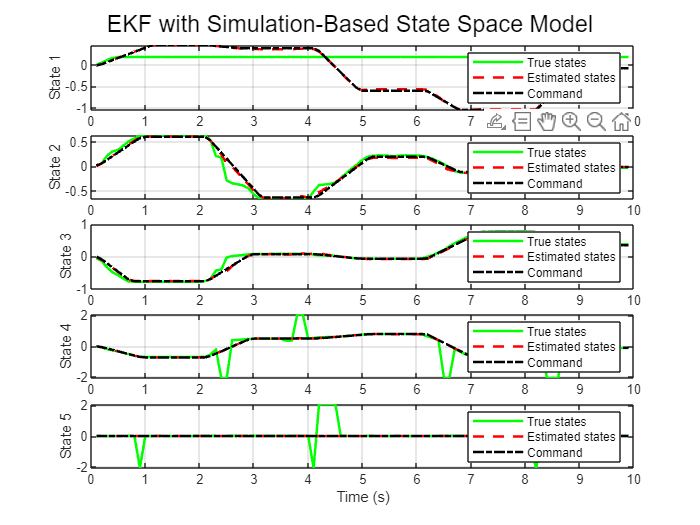

% Plot results
t = (1:N) * dt;
figure;
for i = 1:state_dim
    subplot(state_dim, 1, i);
    plot(t, x_true(i, :), 'g-', 'LineWidth', 1.5); hold on;
    plot(t, x_est_history(i, :), 'r--', 'LineWidth', 1.5); hold on;
    plot(t, U(:, i), 'k-.', 'LineWidth', 1.5); hold on;
    ylabel(['State ', num2str(i)]);
    legend('True states', 'Estimated states', 'Command');
    grid on;
end
xlabel('Time (s)');
sgtitle('EKF with Simulation-Based State Space Model');

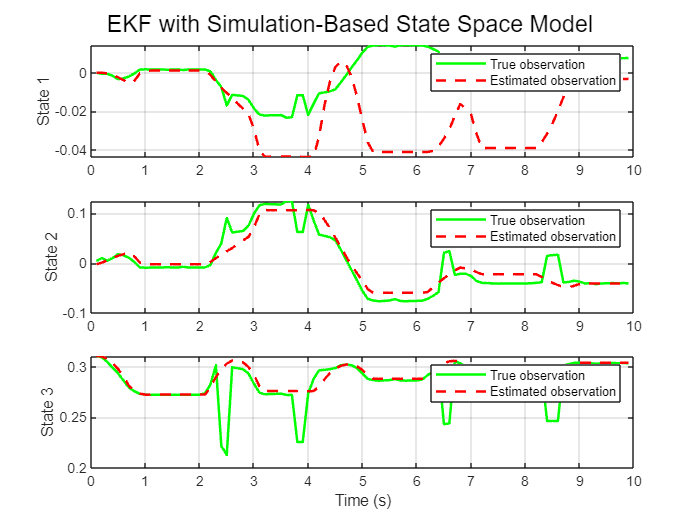


figure;
for i = 1:obs_dim
    subplot(obs_dim, 1, i);
    plot(t, Z(:, i), 'g-', 'LineWidth', 1.5); hold on;
    plot(t, z_est_history(i, :), 'r--', 'LineWidth', 1.5); hold on;
    ylabel(['State ', num2str(i)]);
    legend('True observation', 'Estimated observation');
    grid on;
end
xlabel('Time (s)');
sgtitle('EKF with Simulation-Based State Space Model');



% Helper function

function J = compute_jacobian(f, x, u, delta)
    % Compute the Jacobian numerically using finite differences
    n = length(x); % Dimension of the state vector
    % Check if the function takes two arguments (x, u) or just x
    if nargin(f) == 2
        % Function takes both state and input
        m = length(f(x, u)); % Dimension of the function output
        J = zeros(m, n); % Initialize Jacobian matrix
        for i = 1:n
            dx = zeros(size(x));
            dx(i) = delta; % Perturb the i-th state
            J(:, i) = (f(x + dx, u) - f(x, u)) / delta;
        end
    else
        % Function takes only state
        m = length(f(x)); % Dimension of the function output
        J = zeros(m, n); % Initialize Jacobian matrix
        for i = 1:n
            dx = zeros(size(x));
            dx(i) = delta; % Perturb the i-th state
            J(:, i) = (f(x + dx) - f(x)) / delta;
        end
    end
end


function x_next = simulation_state_transition(x, u, robotSimulator, steps)
    % Set the control command.
    n_inputs = numel(u);
    motorCmds = cell(1, n_inputs);
    for i = 1:n_inputs
        motorCmds{i} = timeseries(u(i)*ones(steps, 1), robotSimulator.simulationTimeStamps);
    end
    motorCmds = robotSimulator.cmdsRadius2Unit(motorCmds);

    % Set the initial values.
    robotSimulator.joint1Init = x(1);
    robotSimulator.joint2Init = x(2);
    robotSimulator.joint3Init = x(3);
    robotSimulator.joint4Init = x(4);
    robotSimulator.setModelParameters(); % Update the parameters in the simulink model

    % Run a simulation and show the results.
    robotSimulator.motorCommands = motorCmds;
    
    motorRespsRadius = robotSimulator.simulateMotorResponses(motorCmds);

    % Example simulation for state transition
    x_next = [
        motorRespsRadius{1}.Data(end);
        motorRespsRadius{2}.Data(end);
        motorRespsRadius{3}.Data(end);
        motorRespsRadius{4}.Data(end);
        motorRespsRadius{5}.Data(end);
    ];
end

function z = simulation_observation(x, robotSimulator)

    motorRespsRadius = cell(1, numel(x));
    for i = 1:numel(x)
        motorRespsRadius{i} = timeseries(x(i), 0);
    end

    trajResponses = robotSimulator.virtualSensor(motorRespsRadius);

    % Example simulation for observation
    z = trajResponses';
end